group = string(y_noout);
% group(group == "1") = "zd958";
% group(group == "2") = "jd20";
% group(group == "3") = "nh816";
% group(group == "4") = 'jh5';

data = X_noout;
format short g
label = group;

train_data  = data(training(cvp), vsel_best);
train_label = label(training(cvp));
test_data   = data(test(cvp), vsel_best);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);


valid_data = X_valid_noout(:, vsel_best);
valid_label = string(y_valid_noout);

rng(1); % For reproducibility
Mdl = TreeBagger(100, train_data, train_label, 'OOBPrediction', 'On', 'Method', 'classification')

Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x13]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   13
         NumPredictorsToSample:                    4
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


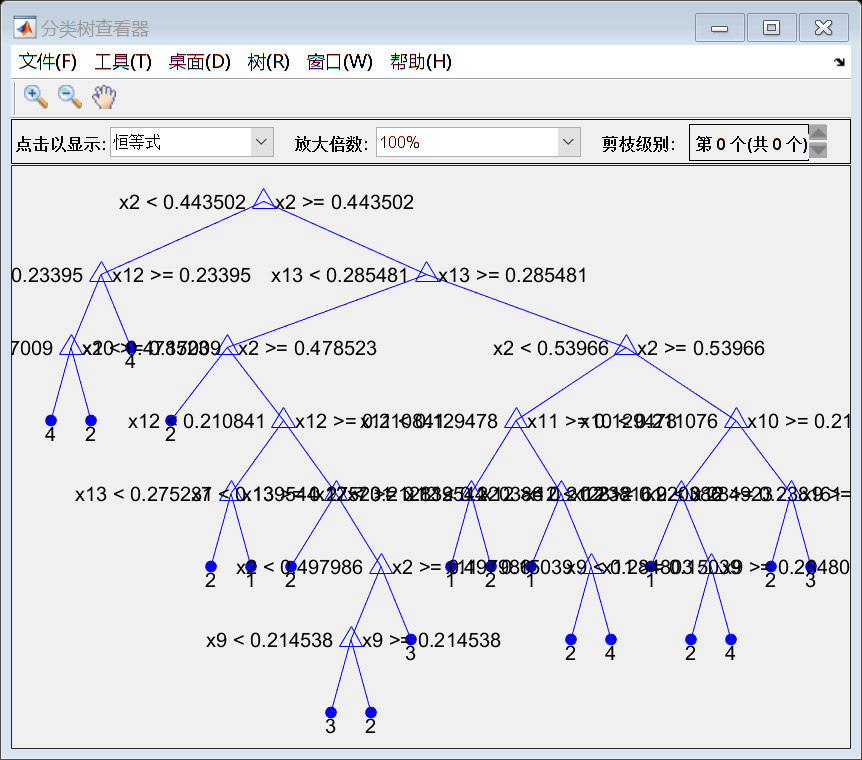


view(Mdl.Trees{1},'Mode','graph')

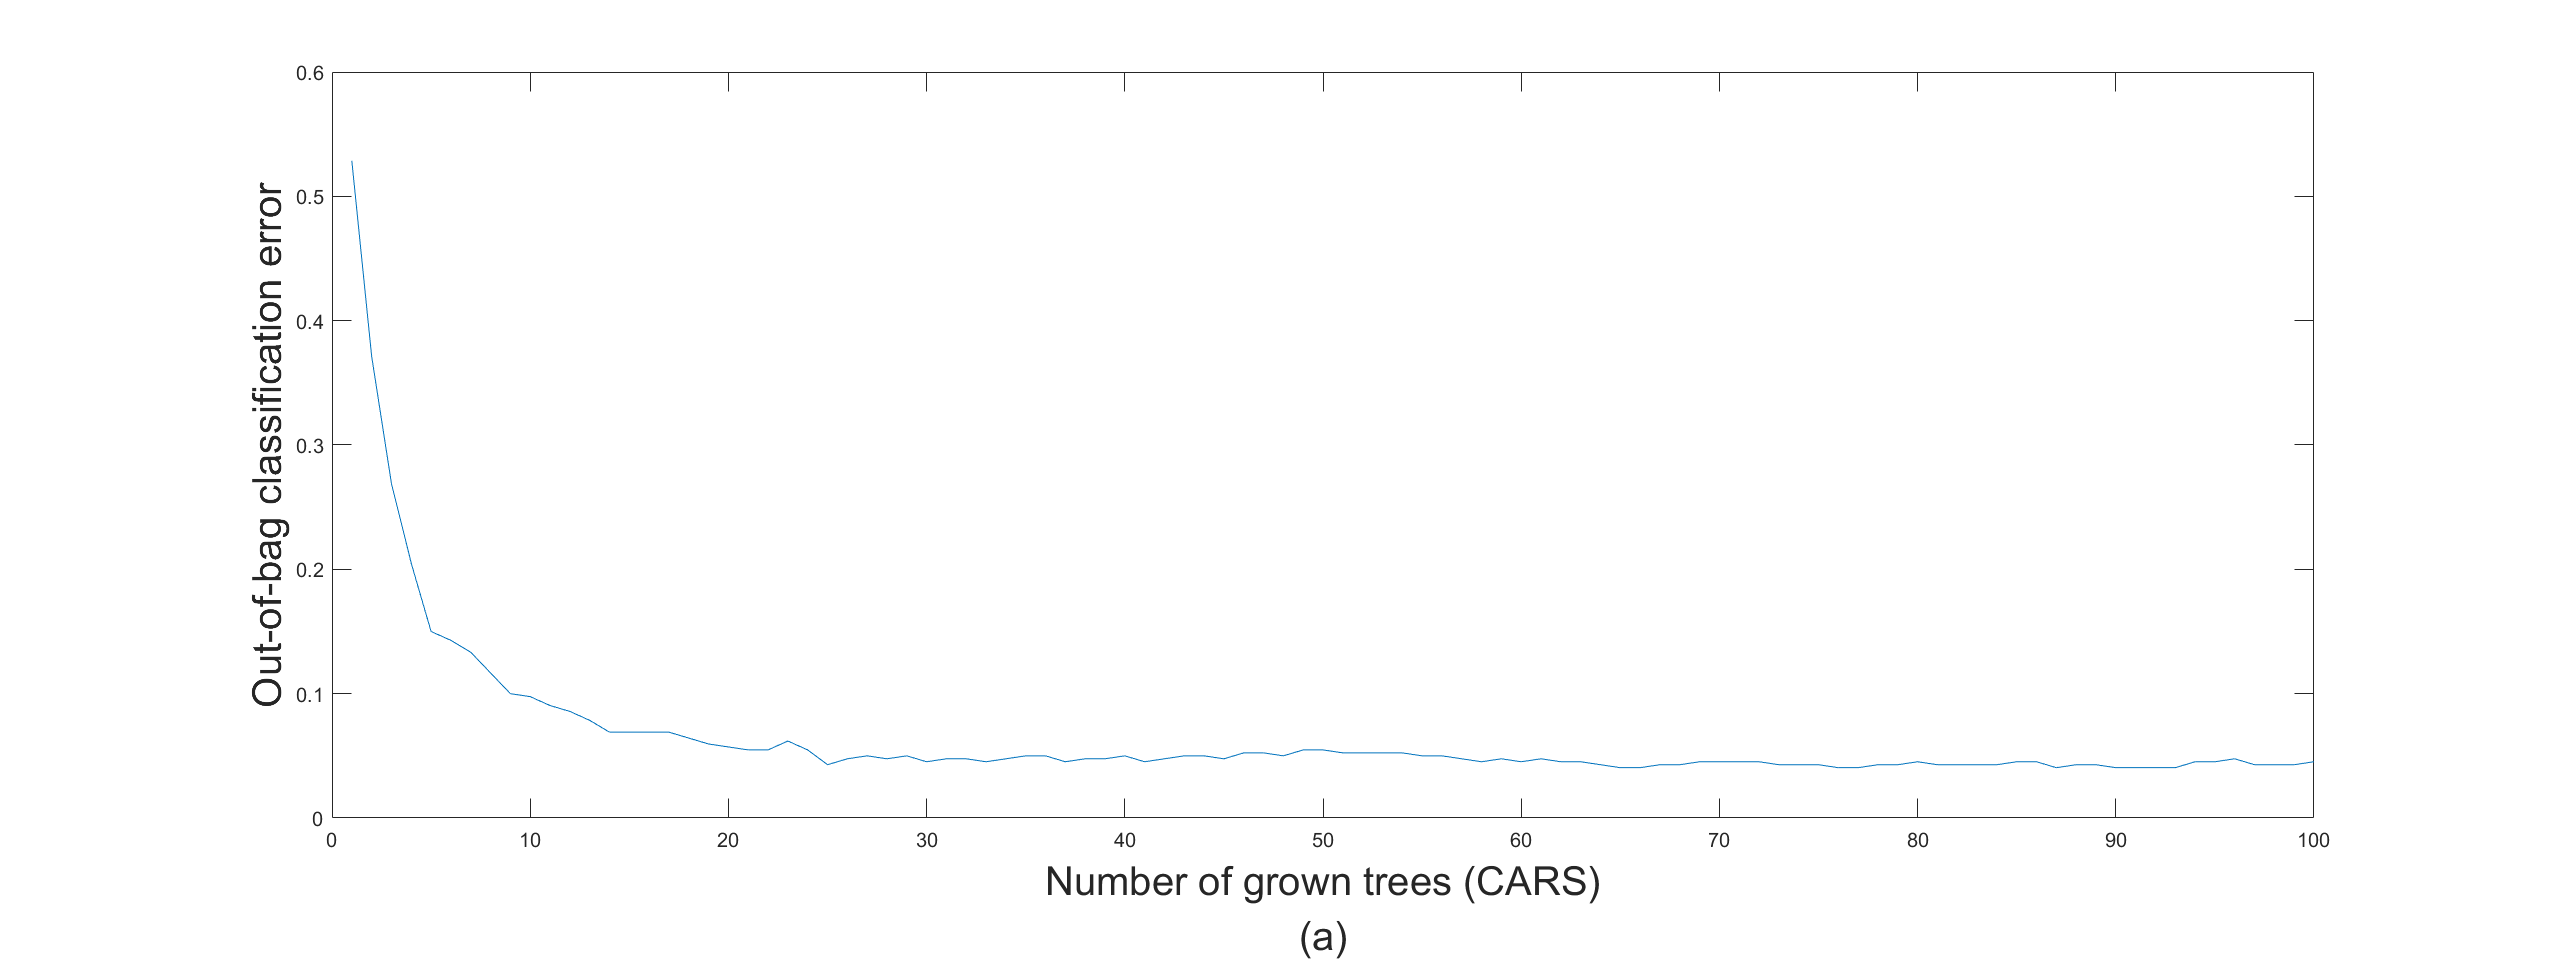

figure('Units','normalized', 'Position', [0, 0, 1, 0.6]);

oobErrorBaggedEnsemble_cars = oobError(Mdl);
plot(oobErrorBaggedEnsemble_cars)
xlabel({'Number of grown trees (CARS)', '(a)'}, "FontSize", 20);
ylabel('Out-of-bag classification error', "FontSize", 20);

simy1 = predict(Mdl, train_data);
simy2 = predict(Mdl, test_data);
simy3 = predict(Mdl, valid_data);

s1 = length(simy1) ;
hitNum1 = 0 ;
for k = 1:s1
    if( simy1(k) == train_label(k))
       hitNum1 = hitNum1 + 1 ;
    end
end
sprintf('识别率是 %3.3f%%', 100 * hitNum1 / s1 )

ans = '识别率是 100.000%'

    
s2 = length(simy2) ;
hitNum2 = 0 ;
for j = 1:s2
    if( simy2(j) == test_label(j))
       hitNum2 = hitNum2 + 1 ;
    end
end
sprintf('识别率是 %3.3f%%', 100 * hitNum2 / s2 )

ans = '识别率是 97.765%'


s3 = length(simy3) ;
hitNum3 = 0 ;
for j = 1:s3
    if( simy3(j) == valid_label(j))
       hitNum3 = hitNum3 + 1 ;
    end
end
sprintf('识别率是 %3.3f%%', 100 * hitNum3 / s3 )

ans = '识别率是 93.750%'

% %%%%%%%%%%%%%%%%%confusion matrix
% C1 = confusionmat(train_label, simy1)
% confusionchart(C1)
% 
% C2 = confusionmat(test_label, simy2)
% confusionchart(C2)